**LEP 7-3 : To find optimum parameter values by minimizing s^2**

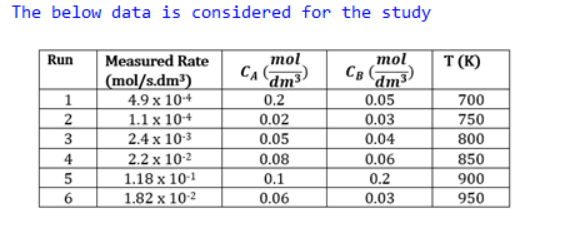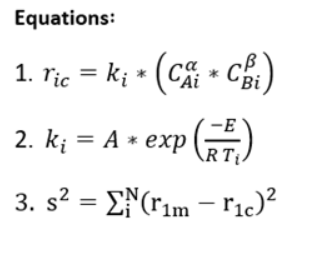

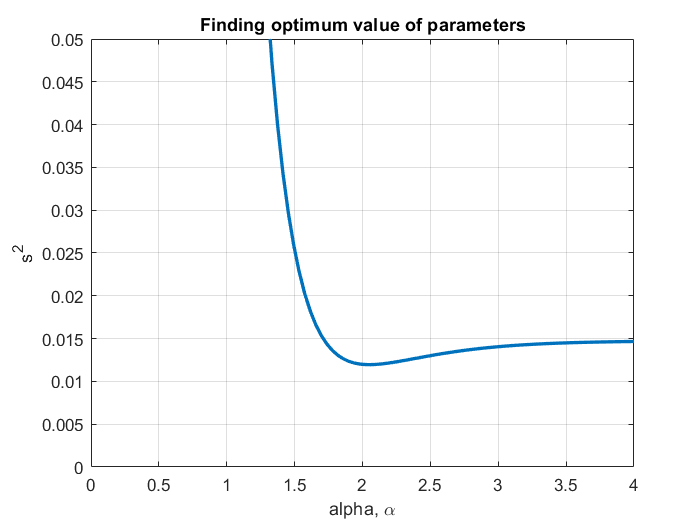

r1m = 4.9*10^-4;
r2m = 1.1*10^-4;
r3m = 2.4*10^-3;
r4m = 2.2*10^-2;
r5m = 1.18*10^-1;
r6m = 1.82*10^-2;
A=8;
Ea=100;
beta=0.5;
alpha=linspace(0,4,100);
k1 = A*exp(-Ea/(8.314*700));
k2 = A*exp(-Ea/(8.314*750));
k3 = A*exp(-Ea/(8.314*800));
k4 = A*exp(-Ea/(8.314*850));
k5 = A*exp(-Ea/(8.314*900));
k6 = A*exp(-Ea/(8.314*950));
for i=1:100
r1c(i) = k1*(0.2.^alpha(i))*(0.05^beta);
r2c(i) = k2.*(0.02.^alpha(i)).*(0.03^beta);
r3c(i) = k3.*(0.05.^alpha(i)).*(0.04^beta);
r4c(i) = k4.*(0.08.^alpha(i)).*(0.06^beta);
r5c(i) = k5.*(0.1.^alpha(i)).*(0.2^beta);
r6c(i) = k6.*(0.06.^alpha(i)).*(0.03^beta);
ssquare(i) = (r1m - r1c(i)).^2 + (r2m - r2c(i)).^2 + (r3m - r3c(i)).^2 + (r4m - r4c(i)).^2 + (r5m - r5c(i)).^2 + (r6m - r6c(i)).^2;
end
plot(alpha,ssquare,'LineWidth',2)
xlabel('alpha, \alpha')
ylabel('s^2')
axis([0 4 0 0.05])
title('Finding optimum value of parameters')
grid on